# Atividade 04_01

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Script

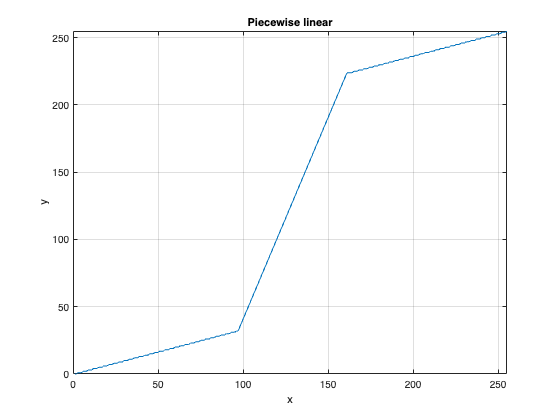

%Piecewise Linear
%Aloca uint8
%para depois usar funcao intlut (y1 é a LUT)
y1 = uint8(zeros([1 256]));
%Equação da reta inferior y = (1/3)*x
y1(1:97) = (1/3)*(0:96);
%Equação da reta intermediária y = 3*x -256
y1(98:161) = 3*(97:160) - 256;
%Equação da reta superior y = (1/3)*x + 170
y1(162:256) = (1/3)*(161:255) + 170;
%Display
figure, plot(y1)
xlim([0 255]), ylim([0 255])
grid on
title('Piecewise linear')
xlabel('x'), ylabel('y')

## **Piecewise-linear**

Aplique a função piecewise-linear para contrast streching especificadas anteriormente (código exemplo) na imagem vpfig.png. Use a função intlut do MATLAB. Mostre a imagem original e a processada.

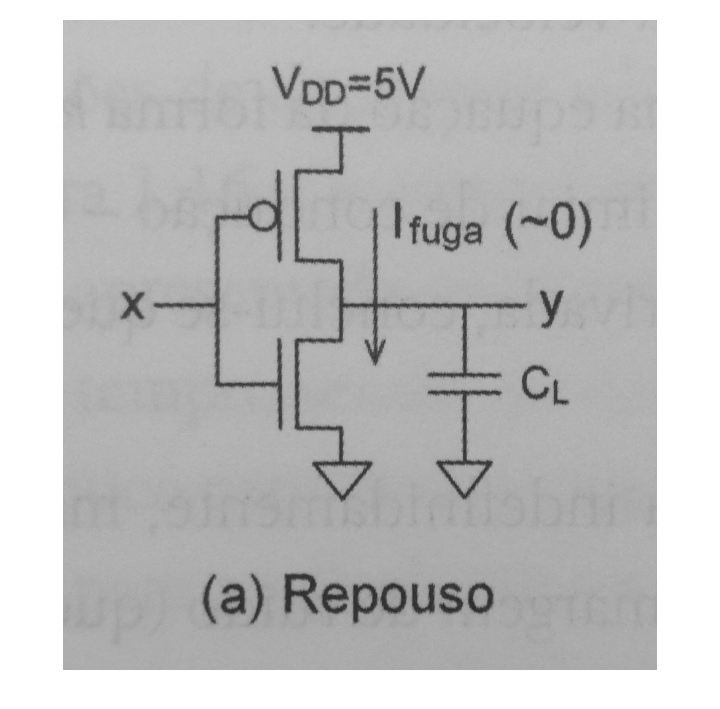

sourceImage = imread("vpfig.png");

processedImage = intlut(sourceImage, y1);

figure, imshow(sourceImage)

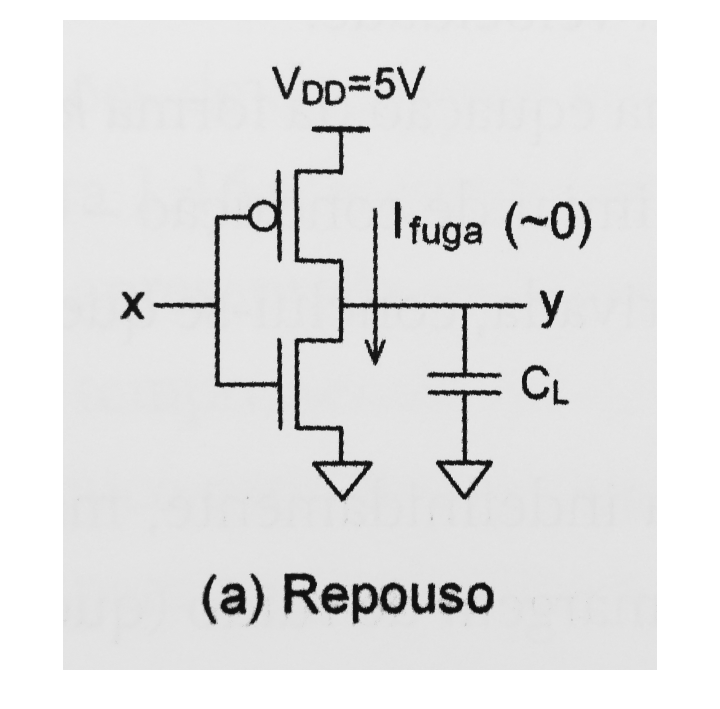

figure, imshow(processedImage);